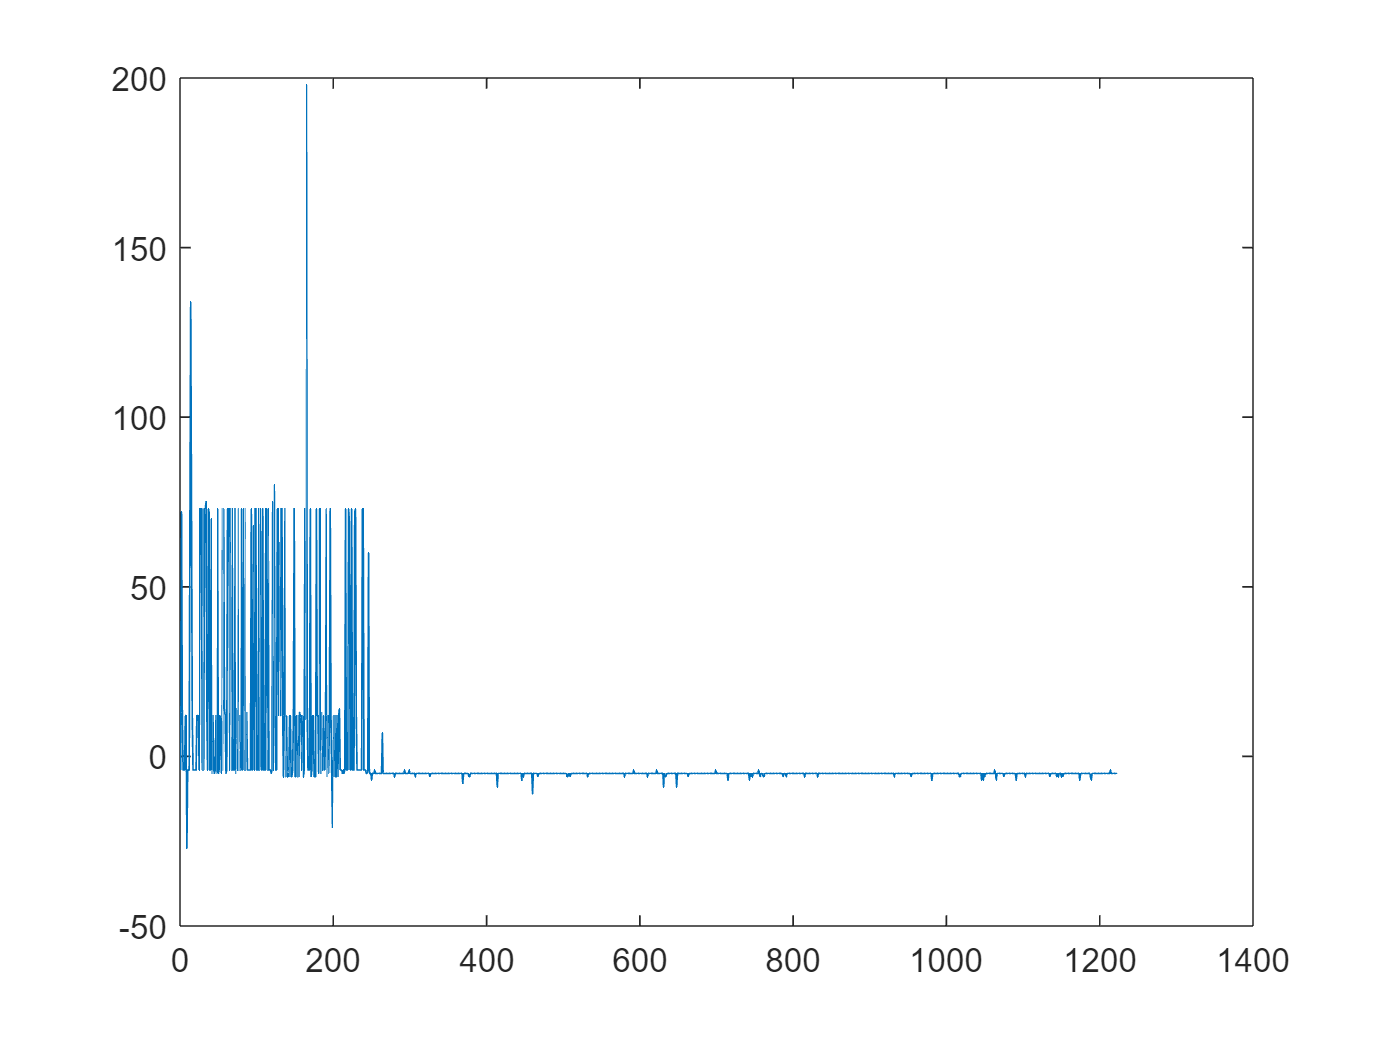

clear all all
pomiary_3out = load("../data/angle_data4.txt");
x = pomiary_3out(:, 1);
y = pomiary_3out(:, 2);

size_data = size(pomiary_3out);

t = 1:1:length(pomiary_3out);
plot(t, y)


k = 71;
tau3 = 31;
T3 = 69;
licz31 = [k];
mian31 = [T3, 1];
[l1,m1]=pade(tau3,1);


u = ones(size(y));

y1ex = iddata(y,u,1)

y1ex =

Time domain data set with 1223 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        



% y1mod = tf(l1, m1);

y1mod = polyfit(t, y, 5)

y1mod =     0.0000   -0.0000    0.0000   -0.0007    0.0053   25.1831


% y1mod = polyval(y1mod, t)
y1mod = poly2sym(y1mod)

$$y1mod = \frac{5529720686069161\,x^{5}}{9903520314283042199192993792}-\frac{8347072451940691\,x^{4}}{4835703278458516698824704}+\frac{4304069002835793\,x^{3}}{2361183241434822606848}-\frac{1593217411350389\,x^{2}}{2305843009213693952}+\frac{765572865645387\,x}{144115188075855872}+\frac{3544206375296925}{140737488355328}$$

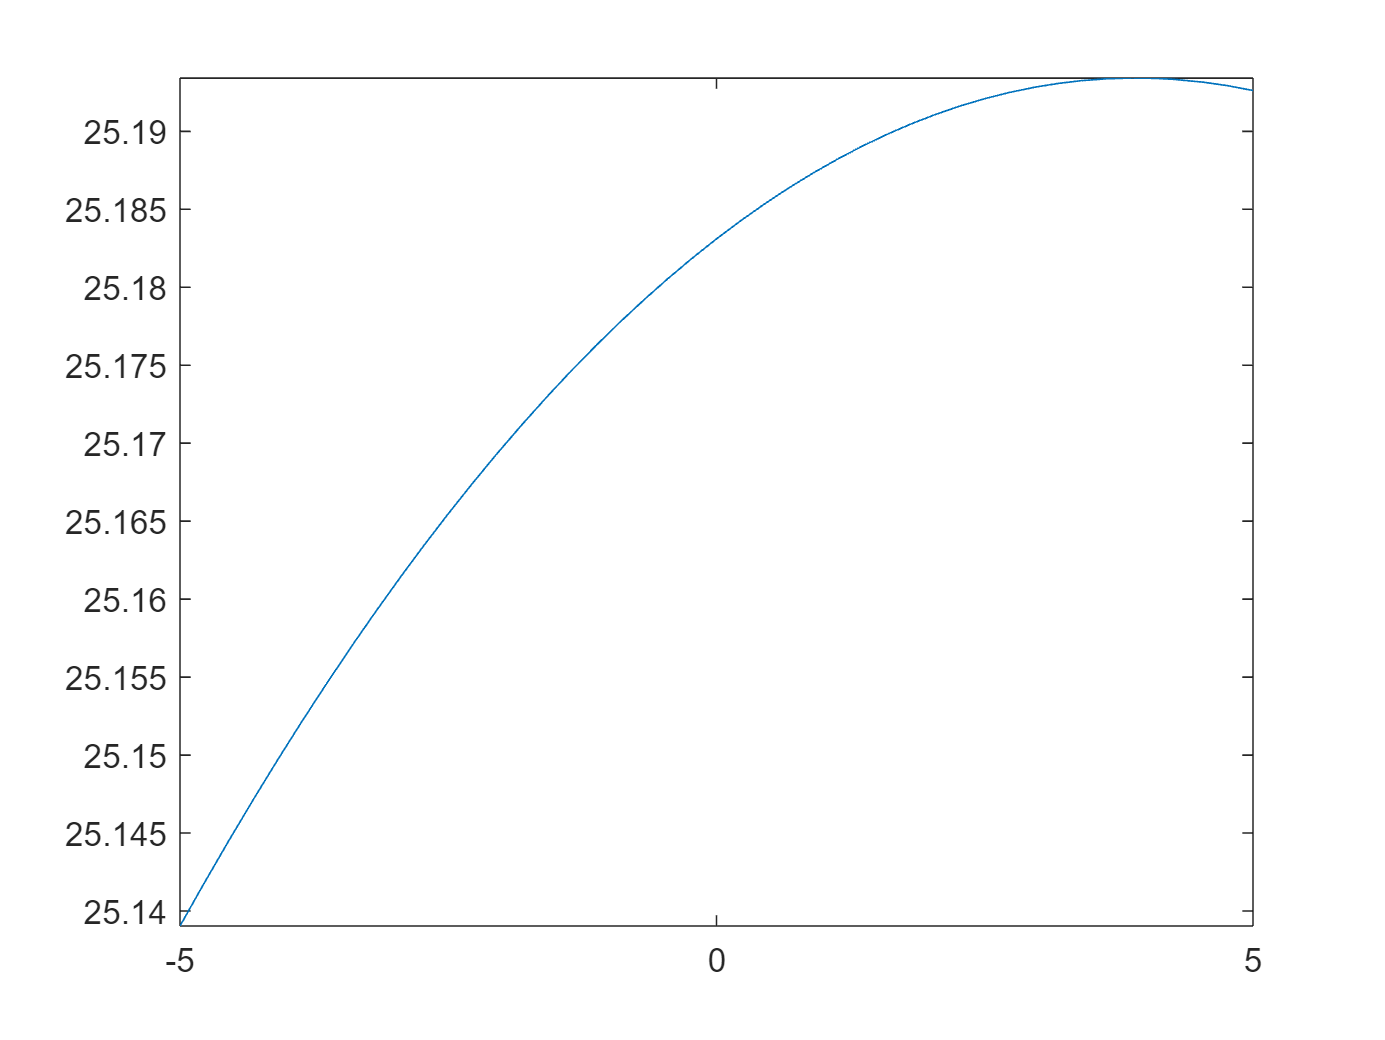

fplot(y1mod)

% y1mod = laplace(y1mod)


compare(y1ex,y1mod,length(pomiary_3out))

Error using compare
Invalid calling syntax for the "compare" command. Type "help compare" for more information.

grid

% stepplot(y2mod)

load("pomiary_3out.mat")

size_data = size(pomiary_3out)

size_data =    300     3


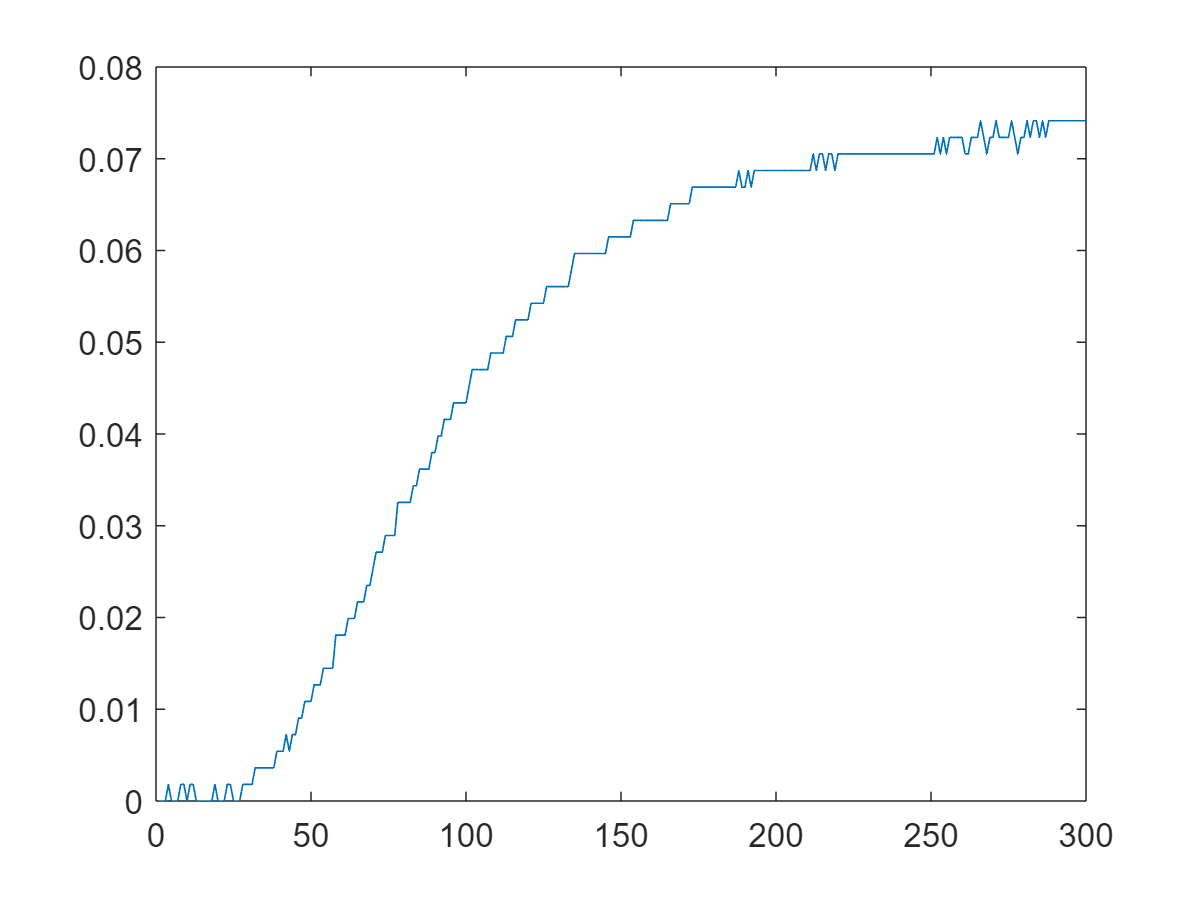


t = 1:1:size_data(1);
y3= pomiary_3out(:,3) - pomiary_3out(1,3);
plot(t, y3)

k3=(y3(300,1)-y3(1,1))/1.0;
tau3 = 31;
T3 = 69;
licz31 = [k3];
mian31 = [T3, 1];
[ld3,md3]=pade(tau3,1);

[l3,m3] = series(licz31,mian31,ld3,md3);
ym3 = step(l3,m3,t);
MSE3 = sum((y3-ym3).^2);

u = ones(size(y3));

y2ex = iddata(y3,u,1)

y2ex =

Time domain data set with 300 samples.
Sample time: 1 seconds                 
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
   u1                                  
                                       


% compare(y2ex,y2mod,300)
% grid
% stepplot(y2mod)

y2mod = tf(l3, m3)

y2mod =
 
    -0.07414 s + 0.004783
  --------------------------
  69 s^2 + 5.452 s + 0.06452
 
Continuous-time transfer function.



[licz, mian] = tfdata(y2mod)

licz = 1×1 cell array
    {[0 -0.0741 0.0048]}


mian = 1×1 cell array
    {[69 5.4516 0.0645]}


licz = licz{1}

licz =          0   -0.0741    0.0048


mian = mian{1}

mian =    69.0000    5.4516    0.0645


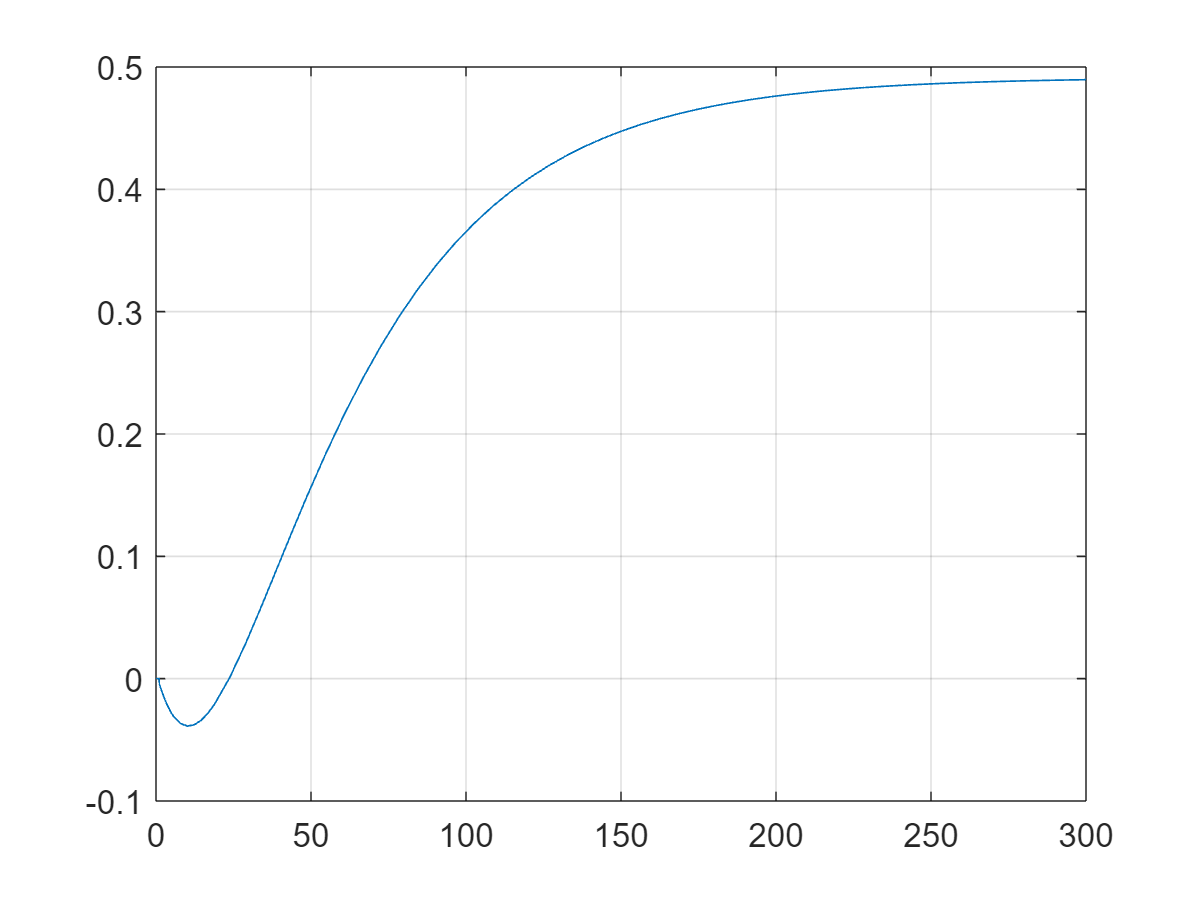


Kp = 3.3;
Ki = 0;
Kd = 4.2;
sim('model',300);
figure
plot(ans.ScopeData.time,ans.ScopeData.signals.values)
grid